%function [rmsx,rmsy,rmsz] = gnsserrors(ENU,T)
format long g
% phonename="Pixel4";
gnd=readtable("ground_truth.csv");
obsname='LLH_T.csv';
obs=readtable(obsname);

gnd{:,3}=gnd{:,3}/1000; % ms convert to s
obs{:,4}=floor(obs{:,4})

obs = 1748×4 table
          Lat                 Long                Height            Epoch   
    ________________    _________________    _________________    __________

    37.4113431300807    -122.025643729142    -1949.72912571579    1303683566
    37.4096808445112     -122.02162400835     200.034780249931    1303683567
    37.4096720770044    -122.021668086961     196.394557396881    1303683568
    37.4098014465082    -122.021913849942     143.131950747222    1303683569
    37.4098126218329    -122.021848332865     130.134635658935    1303683570
    37.4096798571281     -122.02197745724     135.468868965283    1303683571
     37.409687891574    -122.021899811375       95.96413202025    1303683572
    37.2945162202341    -121.962893593504    -2400.12447577622    1303683573
     37.294343819556    -121.962811132956    -2403.55133429822    13036835


wgs84=wgs84Ellipsoid('meter');
%[obsE,obsN,obsU]=geodetic2ecef(wgs84,obs{:,1},obs{:,2},obs{:,3});
obs(
[gndE,gndN,gndU]=geodetic2ecef(wgs84,gnd{:,4},gnd{:,5},gnd{:,6});
obs.E=obsE;obs.N=obsN;obs.U=obsU;
gnd.E=gndE;gnd.N=gndN;gnd.U=gndU;
gnd{:,3}=floor(gnd{:,3})

gnd = 1999×14 table
        collectionName         phoneName     millisSinceGpsEpoch       latDeg            lngDeg         heightAboveWgs84EllipsoidM    timeSinceFirstFixSeconds    hDop    vDop    speedMps    courseDegree            E                    N                   U        
    _______________________    __________    ___________________    _____________    _______________    __________________________    ________________________    ____    ____    ________    ____________    _________________    _________________    

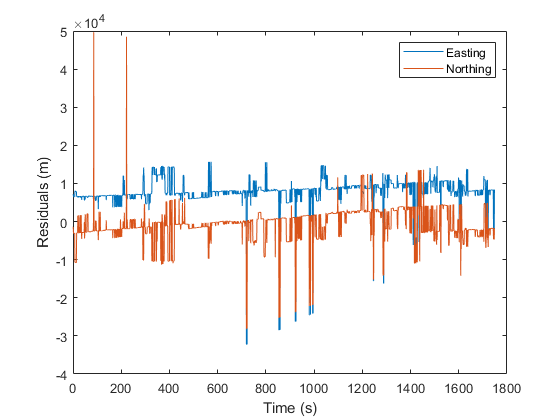

gnd=gnd(:,[1:6 12:14 7:11]);
obs=obs(:,[1:3 5:7 4]);
[ro,co]=size(obs);
vENU=NaN([ro,3]);
obsEpoch=obs{:,co}; % epoch in obs always last var
gndEpoch=gnd{:,3};

for i = 1:ro
    vENU(i,:)=obs{i,4:6}-gnd{gndEpoch==obsEpoch(i),7:9};
end
plot(vENU(:,1))
hold on
plot(vENU(:,2))
legend('Easting','Northing')
xlabel('Time (s)');ylabel('Residuals (m)');
hold off

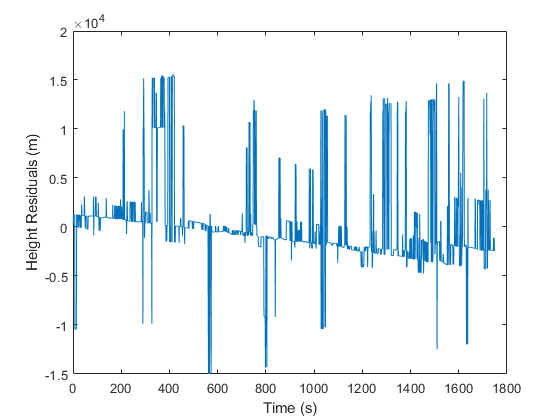

plot(vENU(:,3))
xlabel('Time (s)');ylabel('Height Residuals (m)')

rmse=sqrt(sum(vENU.^2,1,'omitnan')/ro)

rmse =           8920.16248384719          4641.04106469085          4804.42349726635


sqrt(rmse(2)^2+rmse(1)^2)

ans =            10055.275277305


rmseH=sqrt(rmse(1)^2+rmse(2)^2)

rmseH =            10055.275277305


rmseV=rmse(3)

rmseV =           4804.42349726635


%for i=1:
%gnd(1:10,:); % polling rate 1/s=1hz
%obs(1:10,:);

